% clc;
% clear all;
% close all;
addpath(genpath('OFDM-Matlab'))
addpath(genpath('WARPLab-Matlab-Wrapper'))
addpath(genpath('Power-Amplifier-Model'))

% rng('default');
% load('tdd_5.mat')

board = PowerAmplifier();
rms_input = 0.50;

%Setup OFDM
nPRB = 216; % Max. PRB number
Y_n =[];
Z_n =[];
for k = 1:6
for i = 1:3
    if mod(i,3)==0
        ofdm_params.n_subcarriers = 72*12; %v3=500, v4=600
        ofdm_params.subcarrier_spacing = 15e3; % 15/30/60kHz subcarrier spacing
        ofdm_params.constellation = 'QPSK';
        ofdm_params.cp_length = 72; % Number of samples in cyclic prefix.
        ofdm_params.use_windowing = 0;
    
        % For the numerology mu=0, number of symbols per slot = 14 number of slots
        % per frame = 10
        % For the other configurations refer to Table 4.3.2-1 in 3GPP TS 38.211 
        numSymperSlot = 14;
        numSlotperFrame = 10;
        ofdm_params.n_symbols = numSymperSlot*numSlotperFrame;
        modulator = OFDM(ofdm_params);
        
    elseif mod(i,3)==1     
        ofdm_params.n_subcarriers = 72*12; %v3=500, v4=600
        ofdm_params.subcarrier_spacing = 15e3; % 15/30/60kHz subcarrier spacing
        ofdm_params.constellation = '16QAM';
        ofdm_params.cp_length = 72; % Number of samples in cyclic prefix.
        ofdm_params.use_windowing = 0;
    
        % For the numerology mu=0, number of symbols per slot = 14 number of slots
        % per frame = 10
        % For the other configurations refer to Table 4.3.2-1 in 3GPP TS 38.211 
        numSymperSlot = 14;
        numSlotperFrame = 10;
        ofdm_params.n_symbols = numSymperSlot*numSlotperFrame;
        modulator = OFDM(ofdm_params);
        
    elseif mod(i,3)==2
        ofdm_params.n_subcarriers = 72*12; %v3=500, v4=600
        ofdm_params.subcarrier_spacing = 15e3; % 15/30/60kHz subcarrier spacing
        ofdm_params.constellation = '64QAM';
        ofdm_params.cp_length = 72; % Number of samples in cyclic prefix.
        ofdm_params.use_windowing = 0;
    
        % For the numerology mu=0, number of symbols per slot = 14 number of slots
        % per frame = 10
        % For the other configurations refer to Table 4.3.2-1 in 3GPP TS 38.211 
        numSymperSlot = 14;
        numSlotperFrame = 10;
        ofdm_params.n_symbols = numSymperSlot*numSlotperFrame;
        modulator = OFDM(ofdm_params);
         
    end
    % Create TX Data
    [A_n, ~] = modulator.use;
    Z_n = cat( 1, Z_n, A_n);
    i=i+72;
end
end

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

 Cyclic prefix = 72 samples

Y_n = board.transmit(Z_n);  

tx_data_2(:,1) = real(Z_n);
tx_data_2(:,2) = imag(Z_n);

rx_data_2(:,1) = real(Y_n);
rx_data_2(:,2) = imag(Y_n);


## **1.ANN+ANN**

% dataset_tx = rx_dpdmodel;
inputs = tonndata(tx_data_2, false, false);
targets = tonndata(rx_data_2, false, false);

nIterations = 1;
hidden = 12;
net_pa = feedforwardnet([hidden hidden hidden], 'trainlm');
net_dpd = feedforwardnet([hidden hidden hidden], 'trainlm');

net_pa.divideFcn = 'dividerand';  % Divide data randomly
net_pa.divideMode = 'value';  % Divide up every value
net_pa.divideParam.trainRatio = 70/100;
net_pa.divideParam.valRatio = 15/100;
net_pa.divideParam.testRatio = 15/100;

net_pa.layers{1}.transferFcn = 'purelin';
net_pa.layers{2}.transferFcn = 'purelin';
net_pa.layers{3}.transferFcn = 'purelin';
net_pa.layers{4}.transferFcn = 'purelin';
% net_pa.layers{5}.transferFcn = 'purelin';
% net_pa.layers{6}.transferFcn = 'purelin';

net_pa.performFcn = 'msereg';  % Mean squared error
% net_pa.trainParam.goal = 1e-6;
net_pa.trainParam.epochs =1000;

% Train the Network
[net_pa,tr] = train(net_pa,inputs,targets);

%%%%%%%%%%%%%

net_dpd.divideFcn = 'dividerand';  % Divide data randomly
net_dpd.divideMode = 'value';  % Divide up every value
net_dpd.divideParam.trainRatio = 70/100;
net_dpd.divideParam.valRatio = 15/100;
net_dpd.divideParam.testRatio = 15/100;

net_dpd.trainParam.epochs =1000;

net_dpd.layers{1}.transferFcn = 'purelin';
net_dpd.layers{2}.transferFcn = 'purelin';
net_dpd.layers{3}.transferFcn = 'purelin';
net_dpd.layers{4}.transferFcn = 'purelin';
% net_dpd.layers{5}.transferFcn = 'purelin';
% net_dpd.layers{6}.transferFcn = 'purelin';
% net_dpd.layers{7}.transferFcn = 'tansig';
% net_dpd.layers{8}.transferFcn = 'tansig';
% net_dpd.layers{9}.transferFcn = 'tansig';

for i=1:nIterations
     net_dpd.trainParam.epochs = 1000;
    [net_dpd, tr_dpd] = train(net_dpd, inputs, targets);

    outputs_dpd = net_dpd(inputs);

    outputs_pa = net_pa(outputs_dpd);

    inputs = outputs_pa;
end

outputs_all = [inputs{:}];
outputs_all = outputs_all.';

tx_dpdmodel = outputs_all(:,1)+ 1j*outputs_all(:,2);


## **2.LS+ANN**

### **2.1LS**

%ilk olarak sadece PA olan bir sistemde giriş(Z_n) ve çıkış(Y_n) değerleri
%alınıyor. Daha sonra çıkış sinyallerini kullanarak LS algoritmasına göre bir katsayı matrisi bulunuyor.
% Bu katsayı matrisinin tersi ile giriş sinyallerinin(Z_n) çarpımı bize DPD
% nin katsayılarını veriyor.
K = 7;
Q = 4;
N = length(Y_n);
u = zeros(N,(K+1)/2);
U = zeros(N,((K+1)/2)*Q);
memory_orders = 0:2:K-1;

for ii = 1:N
    for jj = 1:length(memory_orders)
        
        u(ii,jj) = Y_n(ii).*abs(Y_n(ii)).^(memory_orders(jj));
        
    end
end

%memory related matrices
U(1,:) = [u(1,:) zeros(1,((K+1)/2)*Q-(K+1)/2)];
U(2,:) = [u(2,:) u(1,:) zeros(1,((K+1)/2)*Q-2*(K+1)/2)];
U(3,:) = [u(3,:) u(2,:) u(1,:) zeros(1,((K+1)/2)*Q-3*(K+1)/2)];

for ii = 4:N
    U(ii,:) = [u(ii,:) u(ii-1,:) u(ii-2,:) u(ii-3,:)] ;%burası değişiyor
end

dpd_hat = pinv(U)*Z_n;     
   
dpd_hat_rshp = reshape(dpd_hat, length(memory_orders), Q);

% board_pa = PowerAmplifier(7, 4, dpd_hat_rshp);%Least Square DPD 
% 
% Z_hat_n = board_pa.transmit(Z_n);
board_dpd = DigitalPreDistorter(7, 4, dpd_hat_rshp);%Least Square DPD 
Fs = 40e6;    % WARP board sampling rate.

Z_hat_n = board_dpd.transmit(Z_n);

board_pa = PowerAmplifier(7,4);

X_n = board_pa.transmit(Z_hat_n);

Y_hat_n = board_pa.transmit(Z_n);


### 2.2 ANN

## Setting Up OFDM signals with Subcarrier Spacing

X_n_11(:,1) = real(Z_n);
X_n_11(:,2) = imag(Z_n);
Y_n_ls(:,1) = real(X_n);
Y_n_ls(:,2) = imag(X_n);

n = length(Y_n);

X_n_1 = X_n_11;
Y_n_nn = Y_n_ls;

for i = 2:n
   X_n_1(i+1,3) = X_n_11(i,1);
   X_n_1(i+1,4) = X_n_11(i,2);
   X_n_1(i+2,5) = X_n_11(i,1);
   X_n_1(i+2,6) = X_n_11(i,2);
   X_n_1(i+3,7) = X_n_11(i,1);
   X_n_1(i+3,8) = X_n_11(i,2);
   
   Y_n_nn(i+1,3) = Y_n_ls(i,1);
   Y_n_nn(i+1,4) = Y_n_ls(i,2);
   Y_n_nn(i+2,5) = Y_n_ls(i,1);
   Y_n_nn(i+2,6) = Y_n_ls(i,2);
   Y_n_nn(i+3,7) = Y_n_ls(i,1);
   Y_n_nn(i+3,8) = Y_n_ls(i,2);
end


## Setting Up Neural Networks and Training


hidden = 12;
    
inputs = tonndata(X_n_1, false, false);
targets = tonndata(Y_n_nn, false, false);

net = feedforwardnet([hidden hidden hidden], 'trainlm');
    
% DPD Neural Network
net.divideFcn = 'dividerand';  % Divide data randomly
net.divideMode = 'value';  % Divide up every value
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 15/100;
net.divideParam.testRatio = 15/100;
    
net.layers{1}.transferFcn = 'purelin';
net.layers{2}.transferFcn = 'purelin';
net.layers{3}.transferFcn = 'purelin';
net.layers{4}.transferFcn = 'purelin';
% net.layers{5}.transferFcn = 'purelin';
% net.layers{6}.transferFcn = 'purelin';

net.trainParam.min_grad = 1e-15;
net.performFcn = 'msereg';  % Mean squared error/mae olacak
% net_pa.trainParam.goal = 1e-6;
net.trainParam.epochs = 1000;
    
% Train the Network
[net,tr] = train(net,inputs,targets);

outputs_all = net(inputs);

pa_out_nn = outputs_all.';

tx_dpdmodel_ls = [];

for i = 1: size(pa_out_nn)-3
    tx_dpdmodel_ls(i) = pa_out_nn{i}(1) +1j*pa_out_nn{i}(2);
end

tx_dpdmodel_ls = tx_dpdmodel_ls.';


## 3.Metrics Analysis


% evm_lsann = norm(tx_dpdmodel_ls-Z_n)/norm(Z_n)
evm_ls = norm(tx_dpdmodel_ls-Z_n)/norm(Z_n)

evm_ls = 0.0253

evm_annann = norm(tx_dpdmodel-Z_n)/norm(Z_n)

evm_annann = 0.0375

evm_tx = norm(Y_n-Z_n)/norm(Z_n)

evm_tx = 0.2759


% nmse_lsann = 10*log10(sum(abs(tx_dpdmodel_ls-Z_n).^2)/sum(abs(Z_n).^2))
nmse_ls = 10*log10(sum(abs(tx_dpdmodel_ls-Z_n).^2)/sum(abs(Z_n).^2))

nmse_ls = -31.9503

nmse_annann = 10*log10(sum(abs(tx_dpdmodel-Z_n).^2)/sum(abs(Z_n).^2))

nmse_annann = -28.5134

nmse_tx = 10*log10(sum(abs(Y_n-Z_n).^2)/sum(abs(Z_n).^2))

nmse_tx = -11.1836

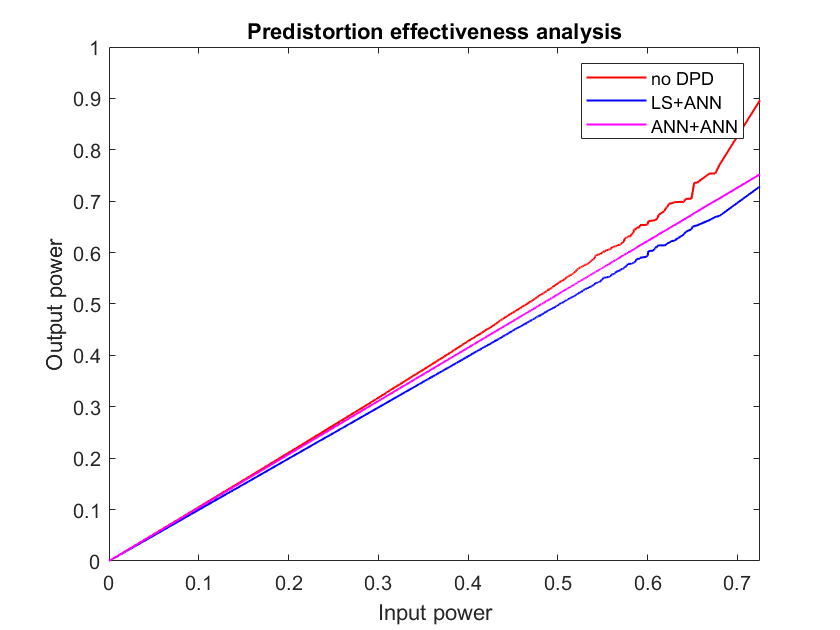


%% Plotting
%% Plot AM-AM after predistortion
figure; %subplot(2,1,1);
plot(sort(abs(Z_n)), sort(abs(Y_n)), 'r', 'LineWidth', 1);
hold on;
plot(sort(abs(Z_n)), sort(abs(tx_dpdmodel_ls)), 'b', 'LineWidth', 1);
hold on;
plot(sort(abs(Z_n)), sort(abs(tx_dpdmodel)), 'm', 'LineWidth', 1);
xlabel('Input power'); 
ylabel('Output power');
legend('no DPD', 'LS+ANN', 'ANN+ANN');
title('Predistortion effectiveness analysis');
axis([min(abs(Z_n)) max(abs(Z_n)) 0 1]); 
hold off;